# LAB1 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

After completing this lab, I’m able to,

1. Use MATLAB to represent impulse function, step function.

2. Use MATLAB to represent discrete-time signals.

3. Explore the effect of simple transformations of the independent variable, such as delaying the signal or reversing its time axis.

4. Use matlab to verify discrete-time systems’ properties such as linearity, time invariance, stability, causality, and inverbily.

5. Use simple linear constant-coefficient difference equations (such as the first-order autoregression equation) to describe discrete-time systems.

## Results and Analysis

### 1.4

#### (a)

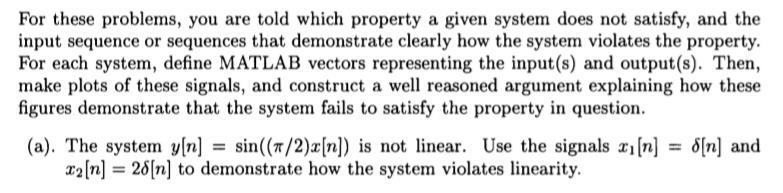

Initialize.

clear; clc; close all;

Create two vectors $x_1$ and $x_2$ and plot them.

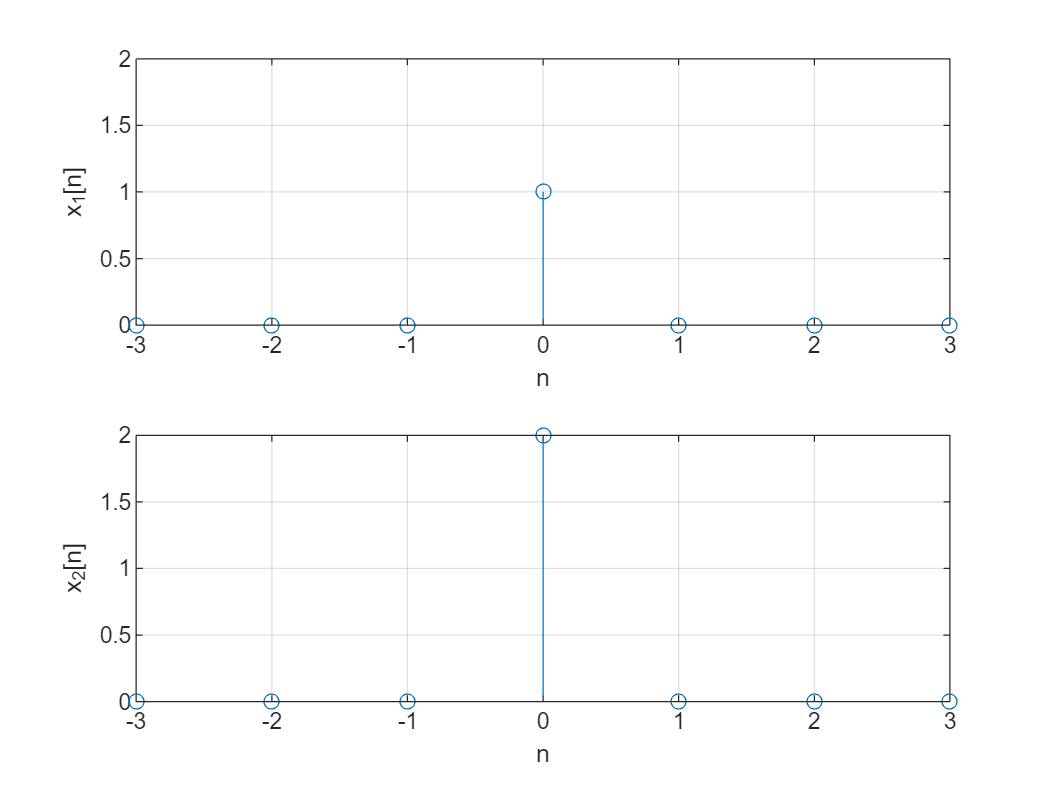

n = -3:3;
x1 = unitimpulse(n);
x2 = 2*x1;
figure;
tiledlayout(2,1);
nexttile;
stem(n,x1);grid on;
xlabel('n');ylabel('x_1[n]');
axis([xlim,0 2]);
nexttile;
stem(n,x2);grid on;
xlabel('n');ylabel('x_2[n]');
axis([xlim,0 2]);

Calculate $y_1 =\sin \left(\frac{\pi }{2}x_1 \left\lbrack n\right\rbrack \right)$ and $y_2 =\sin \left(\frac{\pi }{2}x_2 \left\lbrack n\right\rbrack \right)$.

y1 = sin(pi/2*x1);
y2 = sin(pi/2*x2);

Plot and compare $y_1$and $y_2$ .

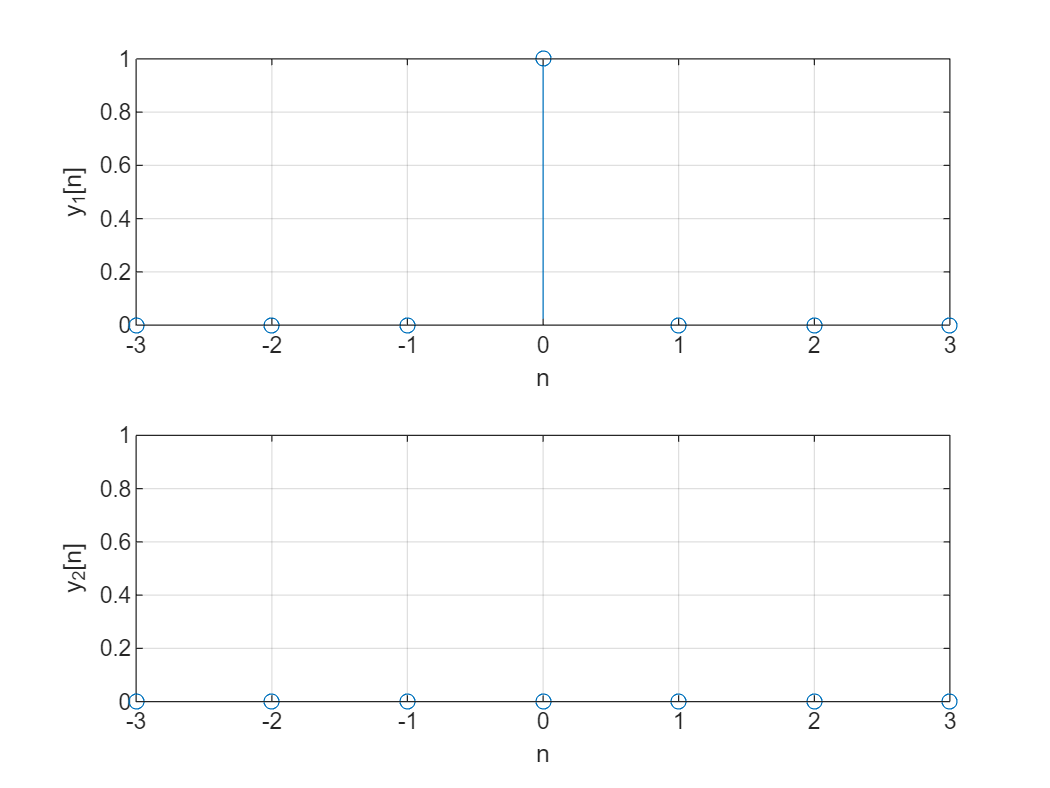

figure;
tiledlayout(2,1);
nexttile;
stem(n,y1);grid on;
xlabel('n');ylabel('y_1[n]');
axis([xlim,0 1])
nexttile;
stem(n,y2);grid on;
xlabel('n');ylabel('y_2[n]');
axis([xlim,0 1]);

From the above figure, we know $x_2=2x_1$, but $y_2 \not= 2y_1$. 

According to the definition, the system is not linear.

#### (b)

Initialize.

clear; clc; close all;

Create one vector $x$ plot it.

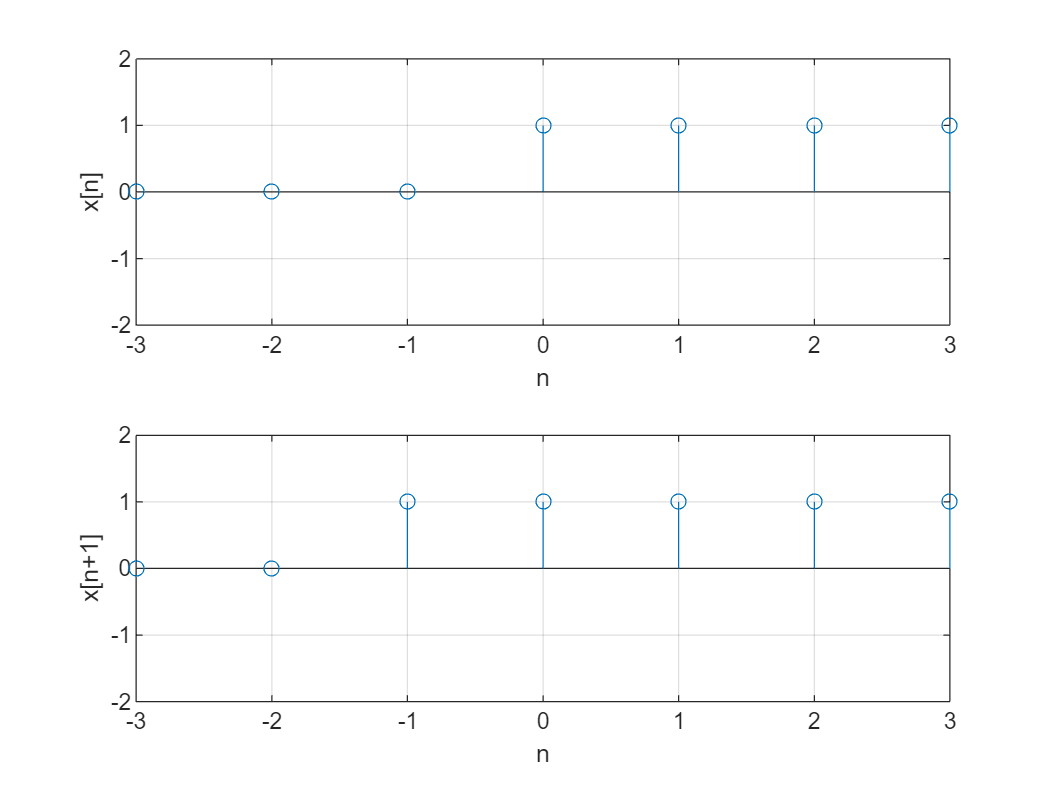

n = -5:9;
x1 = unitstep(n);
x2 = unitstep(n+1);
figure;
tiledlayout(2,1);
nexttile;stem(n,x1);axis([-3 3 -2 2]);grid on;
xlabel('n');ylabel('x[n]');
nexttile;stem(n,x2);axis([-3 3 -2 2]);grid on;
xlabel('n');ylabel('x[n+1]');

Calculate $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack$. 

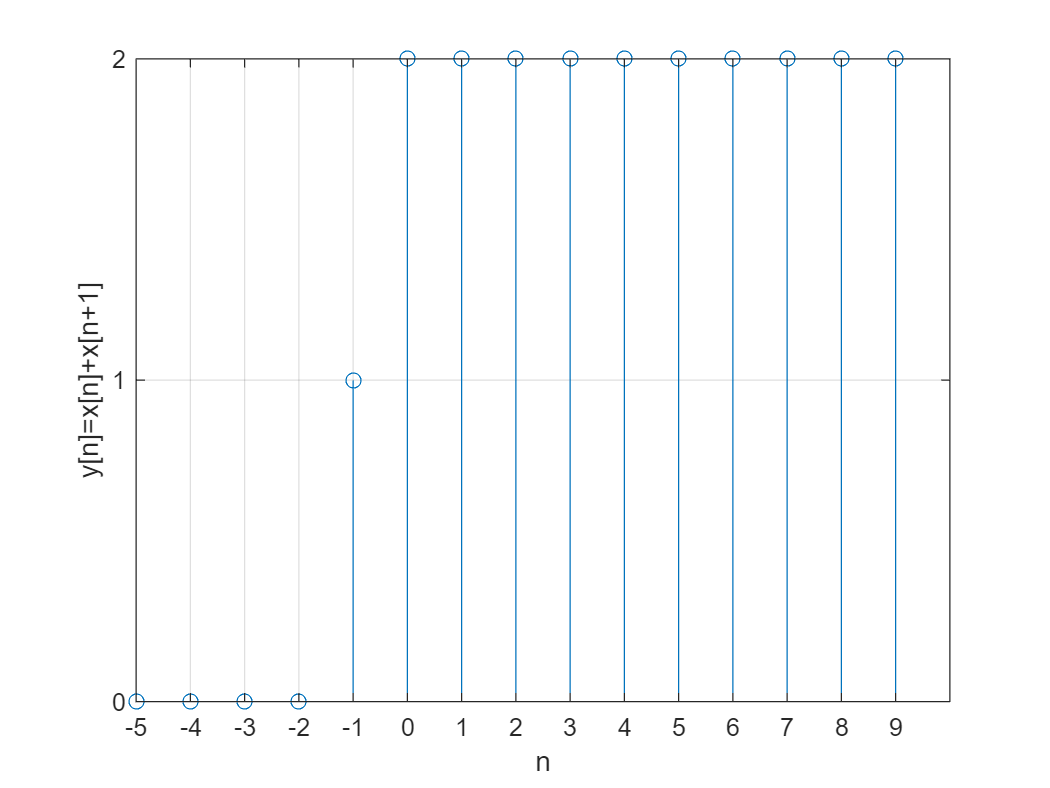

y = x1 + x2;
figure;
stem(n,y);
xlabel('n');
ylabel('y[n]=x[n]+x[n+1]');
xticks(n);
yticks([0 1 2]);
grid on;

When n = 0, y[n] = 1, x[n] = 0, which means there exists an output while the input is 0.

So, the system $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack$ is not causal.

#### (c)

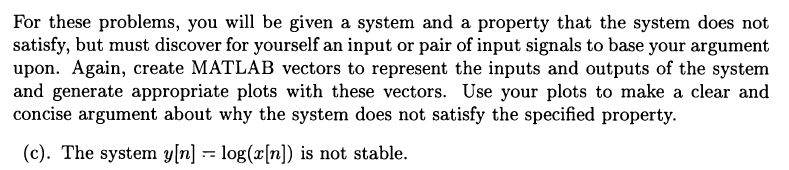

Initialize.

clear; clc; close all;

Assume $x[n] = n (n\geq0)$, create vector $x$ plot it.

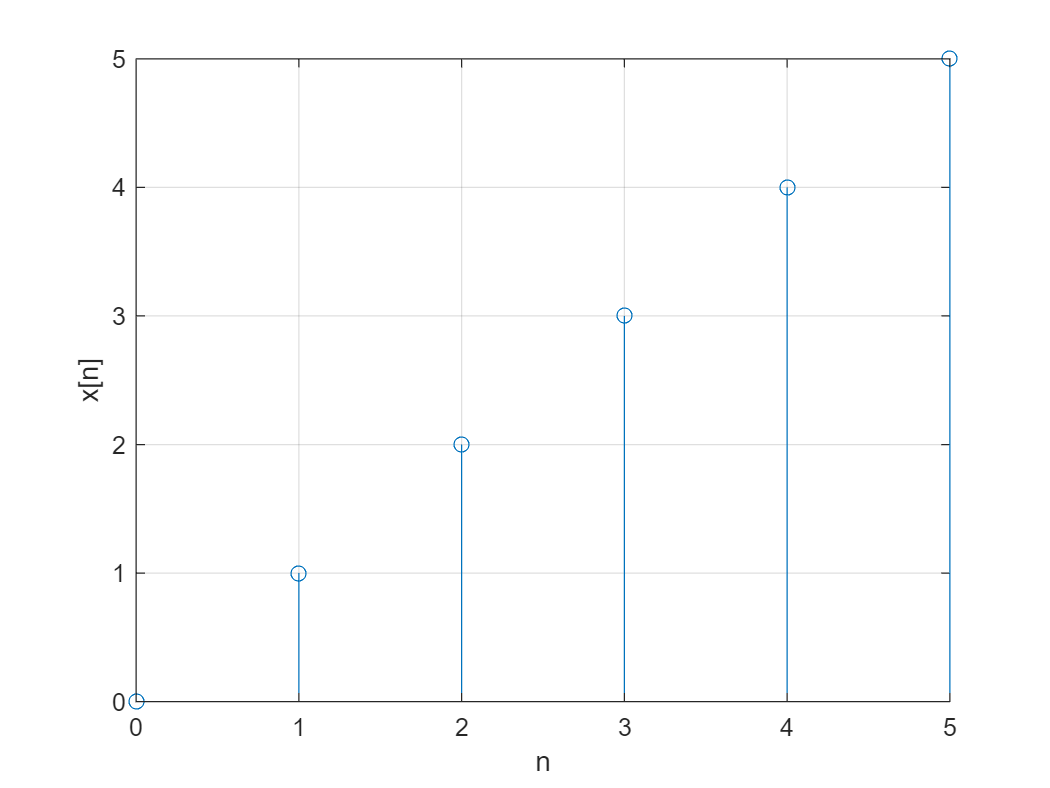

n = 0:5;
x = n;
figure;
stem(n,x);
grid on;
xlabel('n');
xticks(n);
ylabel('x[n]');
yticks(0:5);

Calculate y[n].

y = log(x);

Plot the y[n].

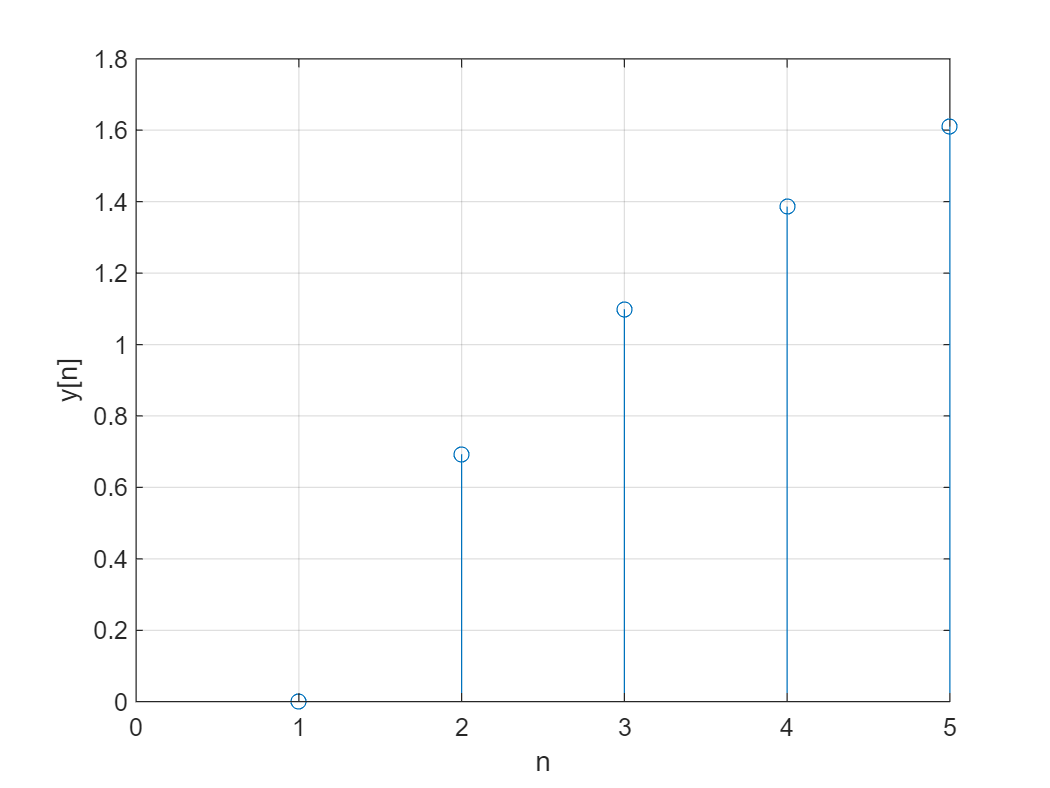

figure;
stem(n,y);
grid on;
axis([0,5,ylim]);
xlabel('n');
xticks(n);
ylabel('y[n]');

Since y[n] is:

y

y =       -Inf         0    0.6931    1.0986    1.3863    1.6094


From the above table, we know y[0] = $-\infty$.

According to the definition, the system is not stable.

#### (d)

Initialize.

clear; clc; close all;

Assume $x[n] = n$, create vector $x$ and plot it.

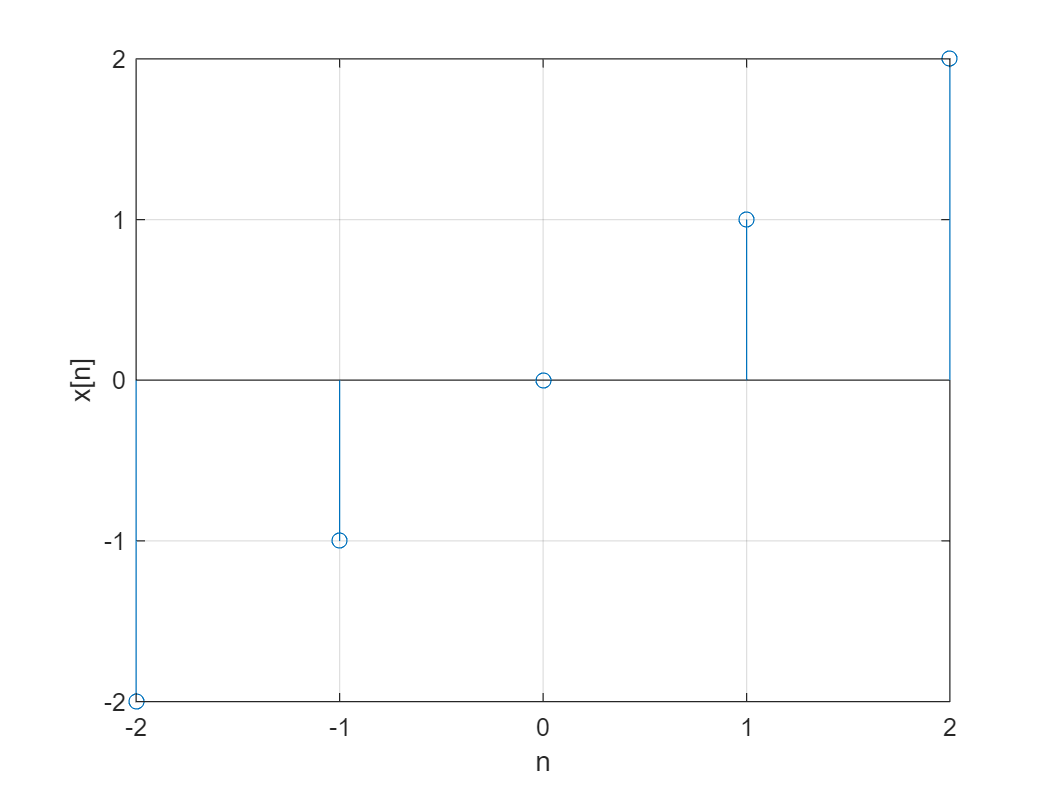

n = -2:2;
x = n;
figure;
stem(n,x);
grid on;
xlabel('n');
xticks(n);
ylabel('x[n]');
yticks(-2:2);

Calculate y[n].

y = sin((pi/2)*x);

Plot the y[n].

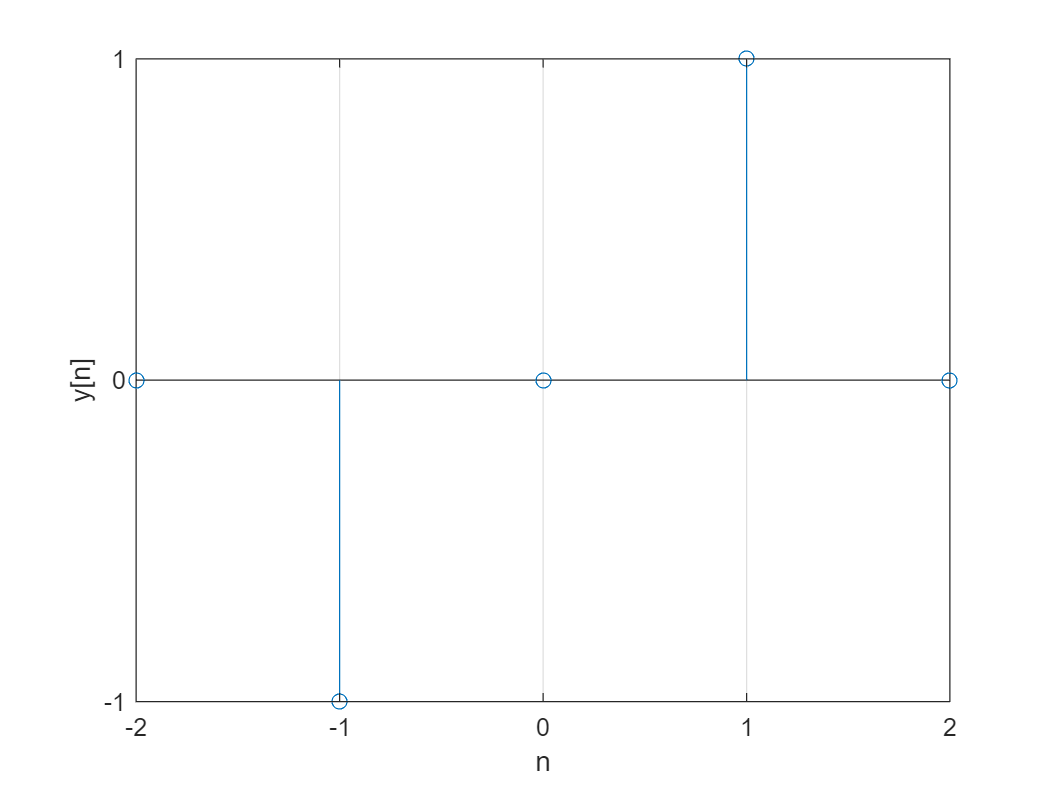

figure;
stem(n,y);
grid on;
xlabel('n');
xticks(n);
ylabel('y[n]');
yticks([-1,0,1]);

From the above figure, we know$x[0] \neq x[2]$ but $y[0] = y[2]$.

According to the definition, the system is not invertible.

### 1.5

#### (a)

#### 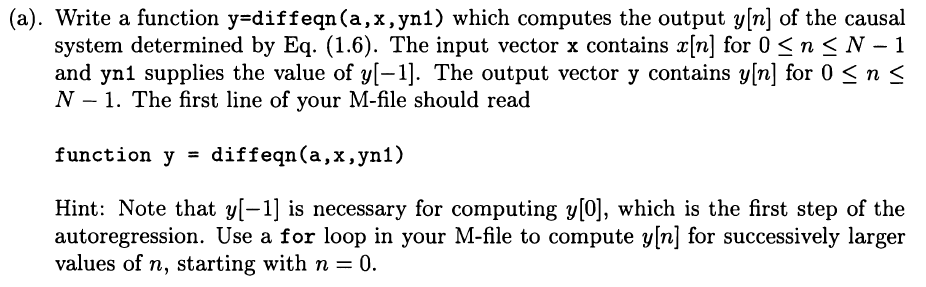

function is written at the end

#### (b)

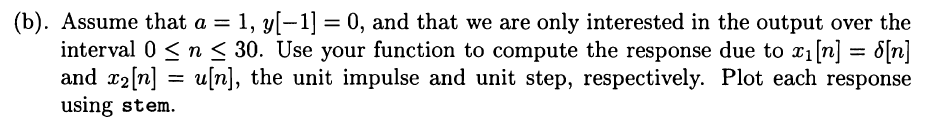

Initialize.

clear; clc; close all;

Create two vectors $x_1$ and $x_2$ and plot them.

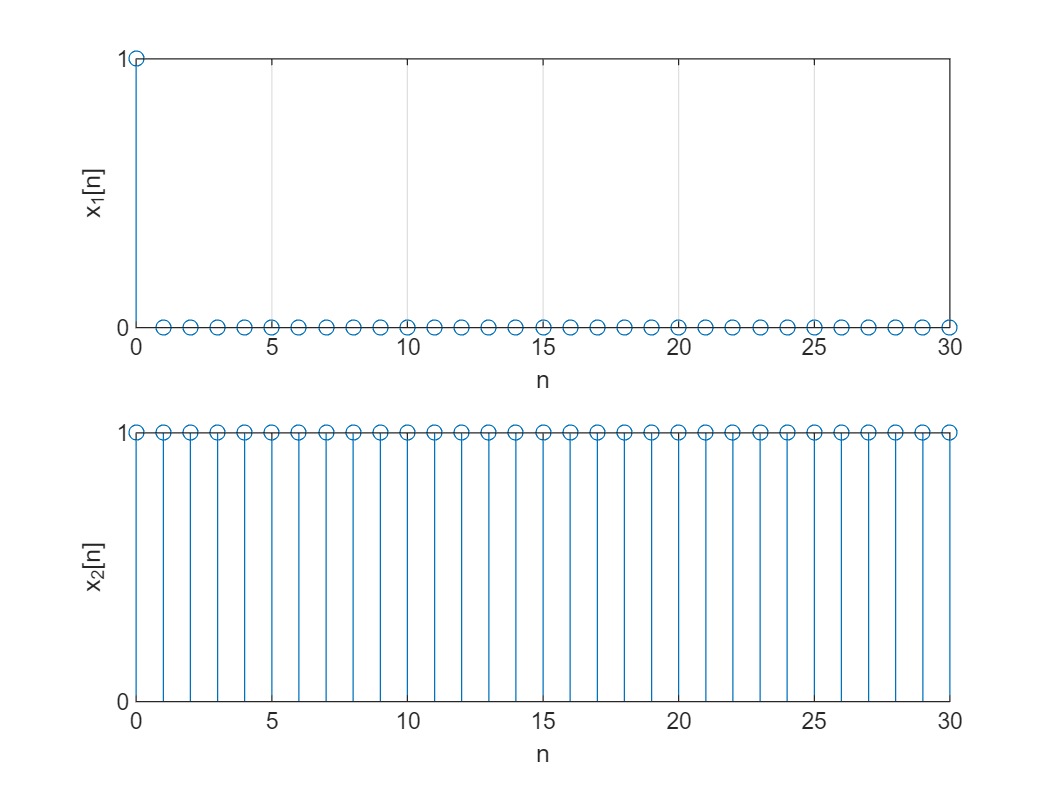

n = 0:30;
x1 = unitimpulse(n);
x2 = unitstep(n);
figure;
subplot(2,1,1),stem(n,x1);
grid on;
xlabel('n');
ylabel('x_1[n]');
yticks([0,1]);
subplot(2,1,2),stem(n,x2);
grid on;
xlabel('n');
ylabel('x_2[n]');
yticks([0,1]);

Calculate $y_1$ and $y_2$.

y1 = diffeqn(1,x1,0);
y2 = diffeqn(1,x2,0);

Plot and compare $y_1$and $y_2$ .

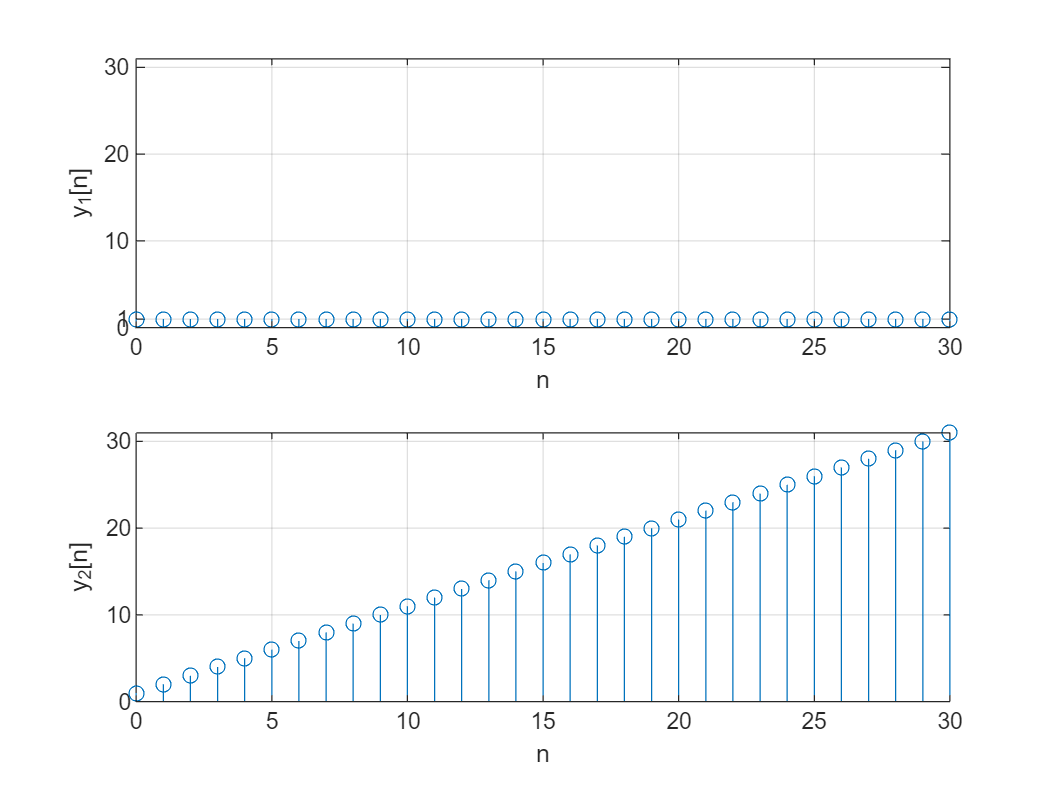

figure;
subplot(2,1,1),stem(n,y1);
grid on;
axis([xlim,0,31]);
xlabel('n');
ylabel('y_1[n]');
yticks([0,1,10,20,30]);
subplot(2,1,2),stem(n,y2);
grid on;
xlabel('n');
ylabel('y_2[n]');

The answer is the graph above.

#### (c)

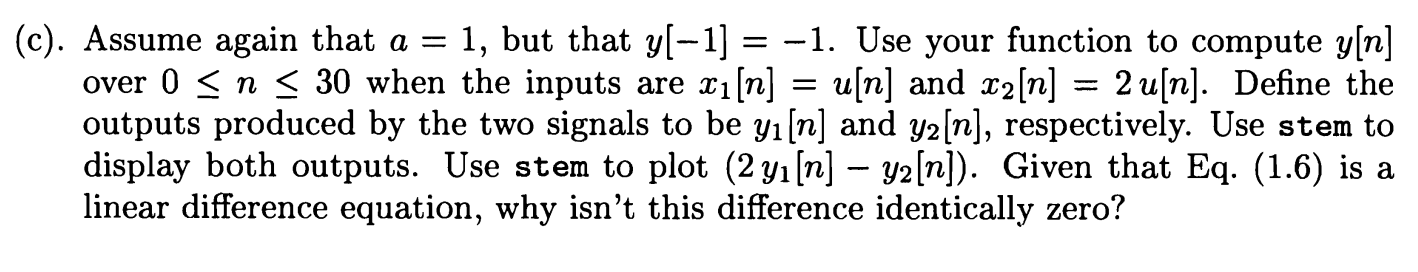

Initialize.

clear; clc; close all;

Create two vectors $x_1 = u[n]$ and $x_2 = 2*u[n]$ and plot them.

a = 1; yn1 = -1; n = 0:30;
x1 = unitstep(n);
x2 = 2 * unitstep(n);

Calculate $y_1[n]=a*y[-1] + x_1[n]$ and $y_2[n]=a*y[-1] + x_2[n]$, and plot them.

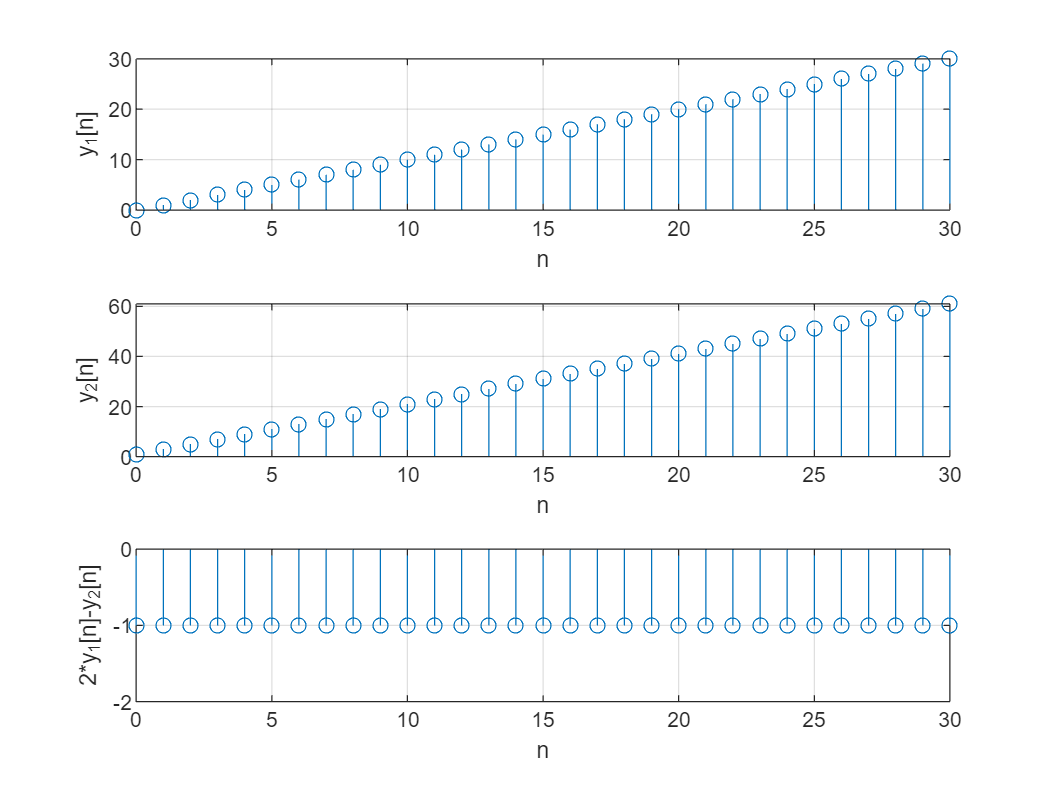

y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);
figure;
tiledlayout(3,1);
nexttile;stem(n, y1);
grid on;xlabel('n');ylabel('y_1[n]');
nexttile;stem(n, y2);
grid on;xlabel('n');ylabel('y_2[n]');
nexttile;stem(n, 2*y1 - y2);
axis([0 30 -2 0]);
grid on;xlabel('n');ylabel('2*y_1[n]-y_2[n]');

Since it's linear, $2*y_1[n] - y_2[n] = a*y[-1] + (2*x_1[n] - x_2[n])$ where  $(2*x_1[n] - x_2[n]) = (2*u_1[n] - u_2[n]) = 0$.

Then $2*y_1[n] - y_2[n] = a*y[-1]$, that is $2*y_1[n] - y_2[n] = -1$.

So, even if Eq. (1.6) is a linear difference equation, this difference can be not identically zero.

### Functions

Unit step function

function y = unitstep (x)
    y = double(x>=0);
end

Unit impulse function

function y = unitimpulse (x)
    y = double(x==0);
end

Function 'diffeqn' in question 1.5

function y = diffeqn (a,x,yn1)
    if length(x) <= 0
        error 'length(x) should larger than 0';
    end
    y = zeros(1, length(x));
    y(1) = a*yn1+x(1);
    for i = 2:length(x)
        y(i) = a*y(i-1)+x(i);
    end
end

## Expeience

涂峻绫：

Through Matlab work, I have a preliminary understanding of Matlab simulation tools in the signal and system of the application of the discipline. Specifically, I practice to use MATLAB to represent impulse function, step function and discrete-time signals，and use matlab to verify discrete-time systems’ properties. Use simple linear constant-coefficient difference equations (such as the first-order autoregression equation) to describe discrete-time systems.

During this lab, I also find some mistakes which are easy to make when coding. It's a good expericence to discover them and to avoid them in the future.

欧阳安男：

Through Matlab work, I have a preliminary understanding of Matlab simulation tools in the signal and system of the application of the discipline.

For each aspects in introduction, the score of myself evaluation is

1. Use MATLAB to represent impulse function, step function. (100)

2. Use MATLAB to represent discrete-time signals. (100)

3. Explore the effect of simple transformations of the independent variable, such as delaying the signal or reversing its time axis. (100)

4. Use matlab to verify discrete-time systems’ properties such as linearity, time invariance, stability, causality, and invertibility. (100)

5. Use simple linear constant-coefficient difference equations (such as the first-order autoregression equation) to describe discrete-time systems. (100)

## Score

涂峻绫（100），欧阳安男（100）